## F1 TRAJECTORY OPTIMIZATION

% 1. Geometric Optimization (V1)

% 2. Physics Comparison (Baseline vs Kamm)

% 3. Iterative Optimization (V2 - Dynamic Path)

clear; clc; close all;


### 1. SETUP & DATA LOADING

fprintf('=== 1. SETUP & TRACK DATA ===\n');


# 1.1 Load Data

try
    track_data = readmatrix('Circuits_Data/Nuerburgring_track.csv');
catch
    error('Track file not found. Please check the file path.');
end

x_center = track_data(:,1);
y_center = track_data(:,2);
w_right  = track_data(:,3);
w_left   = track_data(:,4);
N = length(x_center);


# 1.2 Vehicle Parameters

L = 2.5;                % Wheelbase [m]
delta_max = deg2rad(20);
delta_min = -deg2rad(20);

% Physics Parameters for Speed Profile
param.a_lat_max = 35;   % ~3.5 G (Lateral Grip)
param.a_acc_max = 12;   % Engine Power Limit
param.a_brk_max = 45;   % ~4.5 G (Braking Grip)
param.v_max     = 95;   % ~340 km/h (Top Speed)


# 1.3 Pre-compute Track Headings & Boundaries

theta_track = zeros(N,1);
for k = 1:N-1
    theta_track(k) = atan2(y_center(k+1)-y_center(k), x_center(k+1)-x_center(k));
    if k>=2
        d_th = theta_track(k) - theta_track(k-1);
        if d_th >= pi, theta_track(k) = theta_track(k) - 2*pi; end
        if d_th <= -pi, theta_track(k) = theta_track(k) + 2*pi; end
    end
end
theta_track(N) = theta_track(N-1);

% Left and right boundaries (absolute coordinates)
x_L = x_center - w_left .* sin(theta_track);
y_L = y_center + w_left .* cos(theta_track);
x_R = x_center + w_right .* sin(theta_track);
y_R = y_center - w_right .* cos(theta_track);

% Reference data package for solver
ref.x = x_center; ref.y = y_center; ref.th = theta_track;
ref.xL = x_L; ref.yL = y_L; ref.xR = x_R; ref.yR = y_R;



## 2. PHASE V1: GEOMETRIC OPTIMIZATION (Standard)

fprintf('\n=== 2. PHASE V1: GEOMETRIC PATH (Constant Speed) ===\n');

% YALMIP Variables (Decision Variables)
x=sdpvar(N,1); 
y=sdpvar(N,1); 
theta=sdpvar(N,1); 
delta=sdpvar(N-1,1);
z=sdpvar(N,1);
dtheta=sdpvar(N,1);


## --- Constraints V1 ---

cons = [];
% Track Boundaries
cons = [cons, x == x_L + z.*(x_R-x_L), y == y_L + z.*(y_R-y_L), 0 <= z <= 1];
% Dynamics (Linearized around centerline)
cons = [cons, dtheta == theta - ref.th];
cons = [cons, delta_min <= delta <= delta_max];

for k = 1:N-1
    d = sqrt((ref.x(k+1)-ref.x(k))^2 + (ref.y(k+1)-ref.y(k))^2);
    % Geometric kinematics
    cons = [cons, ((x(k+1)-x(k))*(-sin(ref.th(k))) + (y(k+1)-y(k))*cos(ref.th(k))) == d * dtheta(k)];
    cons = [cons, theta(k+1) == theta(k) + (d/L)*delta(k)];
end

% --- Objective V1 (Minimize Curvature & Length) ---
% Aux variables for abs()
dx_seg=sdpvar(N-1,1); 
dy_seg=sdpvar(N-1,1); 
kappa=sdpvar(N-1,1);
dDelta=sdpvar(N-2,1);

cons_obj = [];
for k = 1:N-1
    d = sqrt((ref.x(k+1)-ref.x(k))^2 + (ref.y(k+1)-ref.y(k))^2);
    cons_obj = [cons_obj, kappa(k) == (theta(k+1)-theta(k))/d];
end

% Weights (V1 Standard)
w_len = 10; w_smooth = 100; w_curv = 1e5;

obj = w_len * sum(dx_seg.^2 + dy_seg.^2) + ... % Approx length
      w_smooth * (dDelta'*dDelta) + ...        % Smooth inputs
      w_curv * (kappa'*kappa);                 % Minimize curvature

ops = sdpsettings('solver','gurobi','verbose',0);
sol = optimize([cons, cons_obj], obj, ops);

if sol.problem ~= 0, warning('V1 Path optimization failed!'); end

% Store V1 Results
path_v1.x = value(x); path_v1.y = value(y); path_v1.th = value(theta);



## 3. PHYSICS COMPARISON (Baseline vs Kamm) on V1 Path

fprintf('\n=== 3. PHYSICS ENGINE COMPARISON (On V1 Path) ===\n');

% 3.1 Recalculate Geometry of V1 Path
dx = diff(path_v1.x); dy = diff(path_v1.y);
ds = sqrt(dx.^2 + dy.^2); ds = [ds; ds(end)];
dth = diff(path_v1.th);
dth(dth>pi)=dth(dth>pi)-2*pi; dth(dth<-pi)=dth(dth<-pi)+2*pi;
k_geo = abs([dth; 0]) ./ (ds + 1e-6);

% --- A. BASELINE (Decoupled) ---
E_base = sdpvar(N,1);
cons_b = [0 <= E_base <= param.v_max^2, E_base(1)==E_base(end)];
for k=1:N-1
    cons_b = [cons_b, E_base(k)*k_geo(k) <= param.a_lat_max]; % Cornering
    acc = (E_base(k+1)-E_base(k))/(2*ds(k));
    cons_b = [cons_b, -param.a_brk_max <= acc <= param.a_acc_max]; % Longitudinal
end
optimize(cons_b, -sum(E_base), ops);
v_base = sqrt(value(E_base));
t_base = sum(ds(1:end-1)./(0.5*(v_base(1:end-1)+v_base(2:end))+1e-3));

% --- B. KAMM DIAMOND (Combined) ---
E_kamm = sdpvar(N,1);
cons_k = [0 <= E_kamm <= param.v_max^2, E_kamm(1)==E_kamm(end)];
for k=1:N-1
    ratio_lat = (E_kamm(k)*k_geo(k)) / param.a_lat_max;
    acc = (E_kamm(k+1)-E_kamm(k))/(2*ds(k));
    % Diamond Constraint: |Lat| + |Long_Brake| <= 1
    cons_k = [cons_k, ratio_lat + abs(acc)/param.a_brk_max <= 1];
    cons_k = [cons_k, acc <= param.a_acc_max]; % Engine limit
end
optimize(cons_k, -sum(E_kamm), ops);
v_kamm = sqrt(value(E_kamm));
t_kamm = sum(ds(1:end-1)./(0.5*(v_kamm(1:end-1)+v_kamm(2:end))+1e-3));

fprintf('   -> Baseline Time : %.3f s\n', t_base);
fprintf('   -> Kamm Time     : %.3f s (More realistic)\n', t_kamm);



## 4. PHASE V2: ITERATIVE OPTIMIZATION (Dynamic Path)

fprintf('\n=== 4. PHASE V2: ITERATIVE OPTIMIZATION ===\n');


=== 4. PHASE V2: ITERATIVE OPTIMIZATION ===



max_iter = 3; 
v_profile = v_kamm; % Start with t  he V1 Kamm speed
hist_time = [];

for iter = 1:max_iter
    fprintf('   -> Iteration %d/%d... ', iter, max_iter);
    
    % --- 4.1 Path Optimization (Weighted) ---
    % Redefine variables to avoid conflicts
    x=sdpvar(N,1); y=sdpvar(N,1); theta=sdpvar(N,1); delta=sdpvar(N-1,1);
    z=sdpvar(N,1); dtheta=sdpvar(N,1); kappa=sdpvar(N-1,1);
    
    % Constraints (Same as V1 + Rate of Change)
    cons = [];
    cons = [cons, x == x_L + z.*(x_R-x_L), y == y_L + z.*(y_R-y_L), 0<=z<=1];
    cons = [cons, dtheta == theta - ref.th];
    cons = [cons, delta_min <= delta <= delta_max];
    
    % Rate of Change (Smoothness)
    d_delta_max = deg2rad(5);
    for k=1:N-2, cons=[cons, -d_delta_max <= delta(k+1)-delta(k) <= d_delta_max]; end
    
    for k = 1:N-1
        d = sqrt((ref.x(k+1)-ref.x(k))^2 + (ref.y(k+1)-ref.y(k))^2);
        cons = [cons, ((x(k+1)-x(k))*(-sin(ref.th(k))) + (y(k+1)-y(k))*cos(ref.th(k))) == d * dtheta(k)];
        cons = [cons, theta(k+1) == theta(k) + (d/L)*delta(k)];
        cons = [cons, kappa(k) == (theta(k+1)-theta(k))/d];
    end
    
    % Adaptive Weights
    w_vec = 2e5 * (v_profile(1:N-1)/95).^1.5 + 5000; % Higher speed = Higher penalty
    w_len_v2=0.1;
    obj = w_len_v2*sum((diff(x)).^2 + (diff(y)).^2) + ...
      100*sum(diff(delta).^2) + ... 
      sum(w_vec .* (kappa.^2));          % Adaptive Curvature
          
    optimize(cons, obj, ops);
    
    % Store Path
    path_v2.x = value(x); path_v2.y = value(y); path_v2.th = value(theta);
    

    ## 4.2 Speed Optimization (Kamm Diamond) on New Path

    dx=diff(path_v2.x); dy=diff(path_v2.y);
    ds=sqrt(dx.^2+dy.^2); ds=[ds; ds(end)];
    dth=diff(path_v2.th);
    dth(dth>pi)=dth(dth>pi)-2*pi; dth(dth<-pi)=dth(dth<-pi)+2*pi;
    k_opt = abs([dth; 0])./(ds+1e-6);
    
    E=sdpvar(N,1);
    cons_v=[0<=E<=param.v_max^2, E(1)==E(end)];
    for k=1:N-1
        rat_l = (E(k)*k_opt(k))/param.a_lat_max;
        acc = (E(k+1)-E(k))/(2*ds(k));
        cons_v=[cons_v, rat_l + abs(acc)/param.a_brk_max <= 1, acc <= param.a_acc_max];
    end
    optimize(cons_v, -sum(E), ops);
    
    v_profile = sqrt(value(E));
    
    % Calc Time
    t_iter = sum(ds(1:end-1)./(0.5*(v_profile(1:end-1)+v_profile(2:end))+1e-3));
    hist_time = [hist_time; t_iter];
    fprintf('Lap Time: %.3f s\n', t_iter);
end

   -> Iteration 1/3... 

Lap Time: 81.715 s


   -> Iteration 2/3... 

Lap Time: 81.793 s


   -> Iteration 3/3... 

Lap Time: 81.809 s



t_final = hist_time(end);
v_final = v_profile;

## 5. VISUALIZATION & ANALYSIS

fprintf('\n=== 5. GENERATING PLOTS ===\n');


=== 5. GENERATING PLOTS ===



% FIGURE 1: MAP & TRAJECTORIES
figure('Name','Trajectories','Color','w');
plot(x_L, y_L, 'w', 'LineWidth', 0.5); hold on;
plot(x_R, y_R, 'w', 'LineWidth', 0.5);
plot(x_center, y_center, 'g:', 'DisplayName', 'Centerline');
plot(path_v1.x, path_v1.y, 'b--', 'LineWidth', 1.5, 'DisplayName', 'V1 (Geo Only)');
plot(path_v2.x, path_v2.y, 'r-', 'LineWidth', 2, 'DisplayName', 'V2 (Dynamic)');
raceline_file = 'Circuits_Data/Nuerburgring_raceline.csv';

% Load Raceline TUM
fprintf('Loading TUM raceline...\n');

Loading TUM raceline...


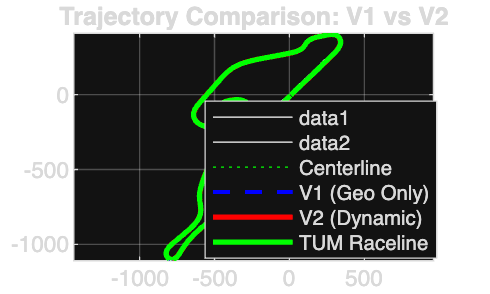

opts2 = detectImportOptions(raceline_file);
opts2.Delimiter = ',';
opts2.VariableNamingRule = 'preserve';
data_race = readtable(raceline_file, opts2);
x_race_raw = data_race.("# x_m");
y_race_raw = data_race.y_m;
plot(x_race_raw, y_race_raw, 'g-', 'LineWidth', 2, 'DisplayName', 'TUM Raceline');
legend('Location', 'best');
title('Optimized Racing Line');
axis equal; grid on;
legend; axis equal; grid on; title('Trajectory Comparison: V1 vs V2');

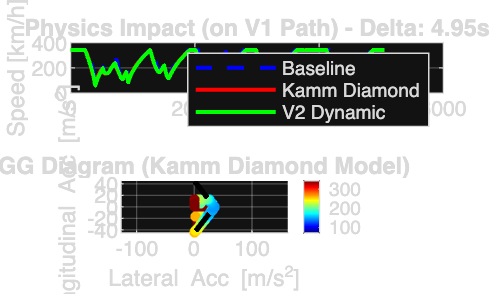


% FIGURE 2: PHYSICS COMPARISON (Baseline vs Kamm on V1)
figure('Name','Physics Comparison','Color','w');
subplot(2,1,1);
d_cum = [0; cumsum(sqrt(diff(path_v1.x).^2 + diff(path_v1.y).^2))];
plot(d_cum, v_base*3.6, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Baseline'); hold on;
plot(d_cum, v_kamm*3.6, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Kamm Diamond');
plot(d_cum, v_final*3.6, 'g-', 'LineWidth', 1.5, 'DisplayName', 'V2 Dynamic');

ylabel('Speed [km/h]'); title(['Physics Impact (on V1 Path) - Delta: ' num2str(t_kamm-t_base, '%.2f') 's']);
legend; grid on;

subplot(2,1,2);
% GG Diagram Calculation V2 just with KAMM
a_lat = v_kamm(1:end-1).^2 .* k_geo(1:end-1);
a_lon = diff(v_kamm.^2)./(2*ds(1:end-1));
scatter(a_lat, a_lon, 15, v_kamm(1:end-1)*3.6, 'filled');
colorbar; colormap jet;
hold on; 
% Draw Diamond Limit
plot([0 param.a_lat_max 0], [param.a_brk_max 0 -param.a_brk_max], 'k--', 'LineWidth', 2);
xlabel('Lateral Acc [m/s^2]'); ylabel('Longitudinal Acc [m/s^2]');
title('GG Diagram (Kamm Diamond Model V2 (just with KAMM)'); grid on; axis equal;

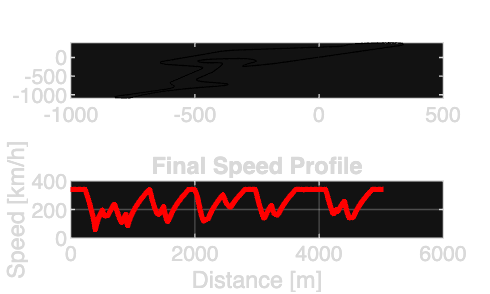


% FIGURE 3: FINAL TELEMETRY (V2)
figure('Name','Final Telemetry','Color','w');
subplot(2,1,1);
scatter(path_v2.x, path_v2.y, 20, v_final*3.6, 'filled');
axis equal; grid on; colorbar; title(['Final V2 Result (Time: ' num2str(t_final,'%.3f') 's)']);
plot(x_L, y_L, 'k'); plot(x_R, y_R, 'k');

subplot(2,1,2);
d_cum_v2 = [0; cumsum(ds(1:end-1))];
plot(d_cum_v2, v_final*3.6, 'r-', 'LineWidth', 2);
ylabel('Speed [km/h]'); xlabel('Distance [m]');
title('Final Speed Profile'); grid on;


fprintf('\nDone. Complete analysis ready.\n');


Done. Complete analysis ready.
